# **圆形极化波的演示**

**        若**$$$E_{ym}=E_{zm}=E_{m}$$$**，且**$$$\psi=\pm\frac{\pi}{2}$$$**，则电场强度的各个分量写为：**


$$\begin{array}{l}
E_y =E_m \cos (\omega t-\beta x)\\
E_z =E_m \cos (\omega t-\beta x\mp \frac{\pi }{2})=\pm E_m \sin (\omega t-\beta x)
\end{array}$$


**        在**$x=0$**的等相面上，则有**


$$\begin{array}{l}
E_y =E_m \cos \omega t\\
E_z =\pm E_m \sin \omega t
\end{array}$$


**        合成场强大小为**


$$$$E=\sqrt{E_{y}^{2}+E_{z}^{2}}=E_{\mathrm{m}}$$$$


**        合成场强矢量 E 与 y 轴的夹角为**


$$$$\varphi=\arctan\frac{E_z}{E_y}=\pm\omega t$$$$


**        这种波是典型的圆极化波。**

## **一、沿x方向 phase =-1/2传输时的左旋圆极化波MATLAB动画演示**

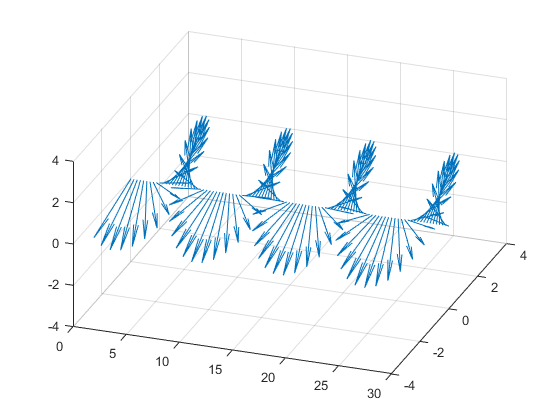

clc
clear
x=(0:0.3:30);                   	%传输距离
l=zeros(size(x)); 
t=0;                          	%时间变量
figure(1)
for i=1:150                    	%帧数
    omega=2*pi;
    Ey=cos(omega*t-0.8*x);        	%电场横向y分量
    Ez=cos(omega*t-0.8*x+pi/2);    	%电场横向z分量
    quiver3(x,l,l,l,Ey,Ez);          	%以(x,0,0)为起点画出传输方向上每一点的电场矢量图
    axis([0,30,-4,4,-4,4]); view(20,40); 	%观察范围
    mov(i)=getframe(gcf);          	%捕捉当前图像作为一帧；
    t=t+0.05;                     	%时间变量变化微小量
end
hold off;

- **动态展示**

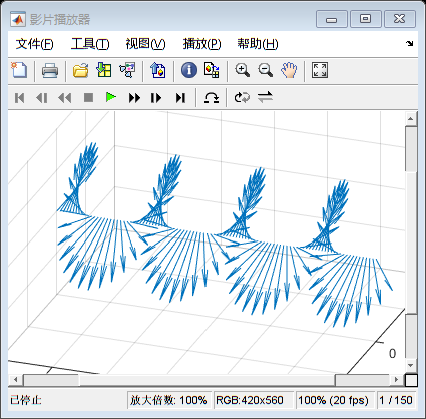

implay(mov);

- **保存为视频文件**

v=VideoWriter('左旋圆极化.avi','Motion JPEG AVI');    %和前面的循环配合，实现动画输出为avi文件
open(v)
writeVideo(v,mov)
close(v)

## **二、沿x方向 phase =-1/2传输时的右旋圆极化波MATLAB动画演示**

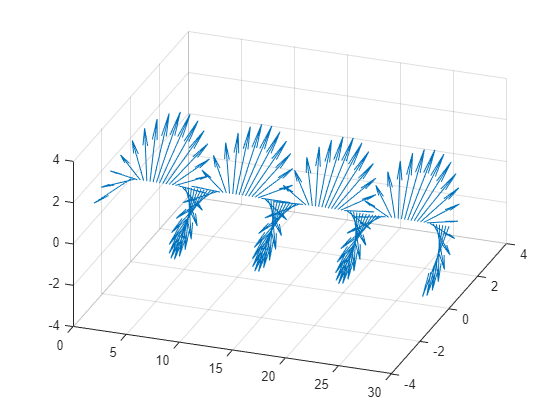

clc
clear
x=(0:0.3:30);                   	%传输距离
l=zeros(size(x)); 
t=0;                          	%时间变量
figure(2)
for i=1:150                    	%帧数
    omega=2*pi;
    Ey=cos(omega*t-0.8*x);        	%电场横向y分量
    Ez=cos(omega*t-0.8*x-pi/2);    	%电场横向z分量
    quiver3(x,l,l,l,Ey,Ez);          	%以(x,0,0)为起点画出传输方向上每一点的电场矢量图
    axis([0,30,-4,4,-4,4]); view(20,40); 	%观察范围
    mov(i)=getframe(gcf);          	%捕捉当前图像作为一帧；
    t=t+0.05;                     	%时间变量变化微小量
end
hold off;

- **动态展示**

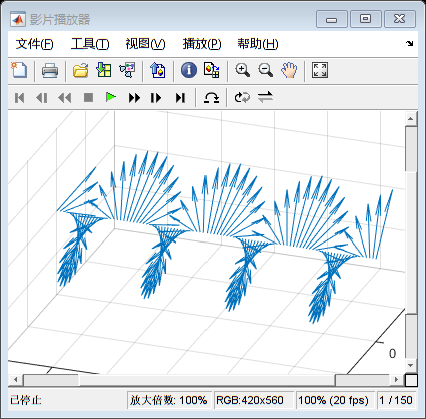

implay(mov);

- **保存为视频文件**

v=VideoWriter('右旋圆极化.avi','Motion JPEG AVI');    %和前面的循环配合，实现动画输出为avi文件
open(v)
writeVideo(v,mov)
close(v)